% -----------------------------------
% ----------- EJERCICIO 2 -----------
% ----- APROXIMACION DE UNA EDO -----
% -----------------------------------

clear; clc; close all;

% 0. Configuración de Estilo (Estilo "Académico" sin LaTeX)
set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');
set(groot, 'defaultTextInterpreter', 'none'); 
set(groot, 'defaultLegendInterpreter', 'none');
set(groot, 'defaultAxesTickLabelInterpreter', 'none');

% 1. Configuración de Datos
numPoints = 100;
X_f = dlarray(linspace(0, 3, numPoints)); 

X_bc = dlarray([0, 3]);        
Y_bc_target = dlarray([2, 5]);

% 2. Inicialización de la Red Neuronal
inputSize = 1;
numNeurons = 4; 
outputSize = 1;
activationName = 'tanh'; 

% Valores iniciales aleatorios
parameters = struct;
parameters.W1 = dlarray(randn(numNeurons, inputSize) * sqrt(2/inputSize));
parameters.b1 = dlarray(zeros(numNeurons, 1));
parameters.W2 = dlarray(randn(outputSize, numNeurons) * sqrt(2/numNeurons));
parameters.b2 = dlarray(zeros(outputSize, 1));

% 3. Configuración del Entrenamiento y GIF
numEpochs = 10000; 
learnRate = 0.005;
lossHistory = zeros(numEpochs, 1);

% --- GIF ---
gifFilename = 'pinn_evo.gif';
numTargetFrames = 200; 

raw_indices = logspace(0, log10(numEpochs), numTargetFrames);
framesToCapture = unique(round(raw_indices)); 

if framesToCapture(end) ~= numEpochs
    framesToCapture = [framesToCapture, numEpochs];
end

% Datos Test
X_test = dlarray(linspace(0, 3, 100));
X_raw = extractdata(X_test)';
Y_exact = X_raw + 2;

% Figura
hFig = figure('Color', 'w', 'Position', [100, 100, 1000, 550]); 

%% 4. Bucle de Entrenamiento
fprintf('--- Iniciando entrenamiento de %d épocas ---\n', numEpochs);

--- Iniciando entrenamiento de 10000 épocas ---


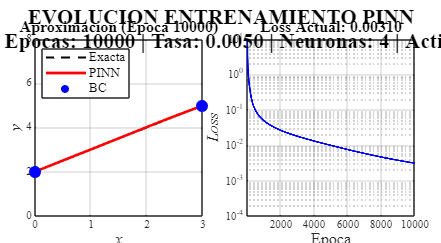

Época    1 | Loss: 14.916908
Época    2 | Loss: 13.829437
Época    3 | Loss: 12.850224
Época    4 | Loss: 11.964765
Época    5 | Loss: 11.161432
Época    6 | Loss: 10.430683
Época    7 | Loss: 9.764527
Época    8 | Loss: 9.156151
Época    9 | Loss: 8.599664
Época   10 | Loss: 8.089916
Época   11 | Loss: 7.622366
Época   12 | Loss: 7.192978
Época   13 | Loss: 6.798153
Época   14 | Loss: 6.434663
Época   15 | Loss: 6.099608
Época   16 | Loss: 5.790374
Época   17 | Loss: 5.504605
Época   18 | Loss: 5.240170
Época   19 | Loss: 4.995145
Época   20 | Loss: 4.767790
Época   21 | Loss: 4.556529
Época   22 | Loss: 4.359939
Época   23 | Loss: 4.176732
Época   24 | Loss: 4.005742
Época   26 | Loss: 3.696297
Época   27 | Loss: 3.556027
Época   28 | Loss: 3.424324
Época   29 | Loss: 3.300484
Época   31 | Loss: 3.073900
Época   32 | Loss: 2.970057
Época   34 | Loss: 2.778900
Época   35 | Loss: 2.690769
Época   37 | Loss: 2.527641
Época   39 | Loss: 2.380035
Época   41 | Loss: 2.245928
Época   42 | L


tic;
paramNames = fieldnames(parameters); 

for epoch = 1:numEpochs
    % a) Gradientes
    [loss, gradients] = dlfeval(@modelLoss, parameters, X_f, X_bc, Y_bc_target);
    
    % b) Actualización
    for k = 1:numel(paramNames)
        name = paramNames{k};
        parameters.(name) = parameters.(name) - learnRate * gradients.(name);
    end
    
    lossHistory(epoch) = extractdata(loss);
    currentLoss = extractdata(loss);
    
    % --- GENERACIÓN DEL GIF ---
    if ismember(epoch, framesToCapture)
        
        fprintf('Época %4d | Loss: %.6f\n', epoch, currentLoss);
        
        % Predicción
        Y_pred = forward(parameters, X_test);
        Y_pred_raw = extractdata(Y_pred)';
        
        % Limpiar figura
        clf(hFig);
        
        % --- TÍTULOS ---
        titleStr = 'EVOLUCION ENTRENAMIENTO PINN';
        subtitleStr = sprintf('Parámetros: Epocas: %d | Tasa: %.4f | Neuronas: %d | Activacion: %s', ...
                              numEpochs, learnRate, numNeurons, activationName);
        
        % sgtitle
        sgtitle({titleStr, subtitleStr}, 'FontWeight', 'bold', 'FontSize', 16);
        
        pos1 = [0.08, 0.11, 0.38, 0.73]; % Izquierda
        pos2 = [0.56, 0.11, 0.38, 0.73]; % Derecha (Misma width/height)

        % --- GRÁFICA 1: Solución ---
        sp1 = subplot(1,2,1);
        set(sp1, 'Position', pos1); % APLICANDO POSICIÓN
        
        plot(X_raw, Y_exact, 'k--', 'LineWidth', 1.5); hold on;
        plot(X_raw, Y_pred_raw, 'r', 'LineWidth', 2);
        scatter([0, 3], [2, 5], 80, 'b', 'filled'); 
        hold off;
        
        title(sprintf('Aproximacion (Epoca %d)', epoch), 'FontSize', 12);
        xlabel('x', 'FontSize', 12, 'FontAngle', 'italic'); 
        ylabel('y', 'FontSize', 12, 'FontAngle', 'italic'); 
        grid on; 
        legend({'Exacta', 'PINN', 'BC'}, 'Location', 'northwest', 'FontSize', 10);
        ylim([0, 8]); 
        
        % --- GRÁFICA 2: Loss ---
        sp2 = subplot(1,2,2);
        set(sp2, 'Position', pos2); % APLICANDO POSICIÓN IDÉNTICA EN TAMAÑO
        
        semilogy(1:epoch, lossHistory(1:epoch), 'b-', 'LineWidth', 1.5);
        
        title(sprintf('Loss Actual: %.5f', currentLoss), 'FontSize', 12);
        xlabel('Época', 'FontSize', 12); 
        ylabel('Loss', 'FontSize', 12, 'FontAngle', 'italic'); 
        grid on; 
        xlim([1, numEpochs]); 
        ylim([1e-4, 10]);     
        
        drawnow; 
        
        % Guardar Frame
        if epoch == framesToCapture(end)
            currentDelay = 3.0; 
        else
            currentDelay = 0.05; 
        end
        
        frame = getframe(hFig); 
        im = frame2im(frame); 
        [imind, cm] = rgb2ind(im, 256); 
        
        if epoch == 1
            imwrite(imind, cm, gifFilename, 'gif', 'Loopcount', inf, 'DelayTime', currentDelay); 
        else
            imwrite(imind, cm, gifFilename, 'gif', 'WriteMode', 'append', 'DelayTime', currentDelay); 
        end
    end
end

toc;

Elapsed time is 134.848548 seconds.


fprintf('Entrenamiento finalizado. GIF guardado como "%s".\n', gifFilename);

Entrenamiento finalizado. GIF guardado como "pinn_evo.gif".




% --- FUNCIONES AUXILIARES ---

function y = forward(params, x)
    z = params.W1 * x + params.b1;
    a = tanh(z); 
    y = params.W2 * a + params.b2;
end

function [loss, gradients] = modelLoss(params, X_f, X_bc, Y_bc_target)
    y_f = forward(params, X_f);
    dy_dx = dlgradient(sum(y_f), X_f, 'EnableHigherDerivatives', true);
    d2y_dx2 = dlgradient(sum(dy_dx), X_f, 'EnableHigherDerivatives', true);
    loss_physics = mean(d2y_dx2.^2);
    y_bc_pred = forward(params, X_bc);
    loss_bc = mean((y_bc_pred - Y_bc_target).^2);
    loss = loss_physics + loss_bc;
    gradients = dlgradient(loss, params);
end